% Dados do problema
C_Mbps = 10; % Capacidade do link em Mbps
C = C_Mbps * 1e6; % Capacidade em bps
D_prop_us = 10; % Atraso de propagação em us
D_prop = D_prop_us * 1e-6; % Atraso de propagação em segundos
lambda = 1000; % Taxa de chegada de pacotes (pps)

% ----------------------
% 4.a. Tamanho médio do pacote e tempo médio de transmissão
% ----------------------

% Pacotes com probabilidade específica
L_especificos = [64, 110, 1518];
P_especificos = [0.19, 0.23, 0.17];
P_esp_total = sum(P_especificos);

% Pacotes 'outros'
P_outros_total = 1 - P_esp_total;
L_outros_valores = [65:109, 111:1517];
N_outros = length(L_outros_valores);
P_outros_i = P_outros_total / N_outros; % Probabilidade de cada valor 'outro'

% Cálculo do Tamanho Médio do Pacote (L_bar)
L_bar = sum(L_especificos .* P_especificos) + sum(L_outros_valores * P_outros_i);
fprintf('4.a. Tamanho médio do pacote (Bytes): %.2f\n', L_bar);

4.a. Tamanho médio do pacote (Bytes): 620.02



% Tempo Médio de Transmissão (T_s_bar)
T_s_bar = (L_bar * 8) / C;
fprintf('4.a. Tempo médio de transmissão (s): %.2e\n', T_s_bar);

4.a. Tempo médio de transmissão (s): 4.96e-04



% ----------------------
% 4.b. Taxa de Transferência Média (Throughput)
% ----------------------

Throughput_bps = lambda * L_bar * 8;
Throughput_Mbps = Throughput_bps / 1e6;
fprintf('4.b. Taxa de Transferência Média (Mbps): %.2f\n', Throughput_Mbps);

4.b. Taxa de Transferência Média (Mbps): 4.96



% ----------------------
% 4.c. Capacidade do Link em Pacotes/Segundo
% ----------------------

mu = 1 / T_s_bar;
fprintf('4.c. Capacidade do Link (pps): %.2f\n', mu);

4.c. Capacidade do Link (pps): 2016.06



% ----------------------
% 4.d. Atrasos no Enfileiramento M/G/1
% ----------------------

% Utilização (rho)
rho = lambda / mu;

% Cálculo do segundo momento de L (E_L2)
L_todos = [L_especificos, L_outros_valores];
P_todos = [P_especificos, repmat(P_outros_i, 1, N_outros)];
E_L2 = sum(L_todos.^2 .* P_todos);

% Segundo momento do tempo de serviço (E_Ts2)
E_Ts2 = (8/C)^2 * E_L2;

% Atraso médio de enfileiramento (W_q) - Pollaczek-Khinchine
W_q = (lambda * E_Ts2) / (2 * (1 - rho));
fprintf('4.d. Atraso médio de enfileiramento (s): %.2e\n', W_q);

4.d. Atraso médio de enfileiramento (s): 4.60e-04



% Atraso médio do sistema (W)
W = W_q + T_s_bar + D_prop;
fprintf('4.d. Atraso médio do sistema (s): %.2e\n', W);

4.d. Atraso médio do sistema (s): 9.66e-04


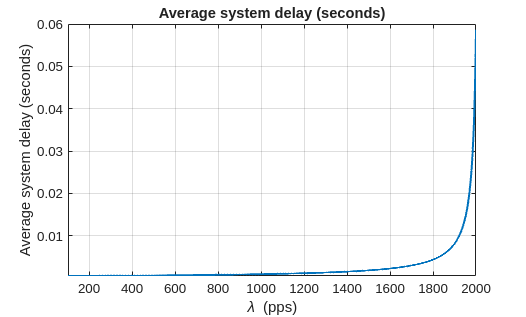

%% Parâmetros Fixos do Sistema
C = 10 * 1e6;       % Capacidade do link (bps)
D_prop = 10 * 1e-6; % Atraso de propagação (segundos)

% Parâmetros de Distribuição do Tamanho do Pacote (Calculados na Resolução Anterior)
L_bar = 620.02;     % Tamanho médio do pacote (Bytes)
E_L2 = 723959.08;   % Segundo momento do tamanho do pacote (Bytes^2)

% Cálculos Derivados
T_s_bar = (L_bar * 8) / C;          % Tempo médio de transmissão (E[T_s])
E_Ts2 = (8/C)^2 * E_L2;             % Segundo momento do tempo de transmissão (E[T_s^2])

%% Variáveis de Plotagem
lambda_min = 100;
lambda_max = 2000;
lambda_pps = lambda_min:1:lambda_max; % Vetor de Taxas de Chegada (pps)

% Taxa de serviço (Capacidade em pps)
mu = 1 / T_s_bar; % mu é aproximadamente 2016.06 pps

% Cálculo da Utilização (rho) e Atraso do Sistema (W)
rho = lambda_pps * T_s_bar;

% Condição de Estabilidade: rho < 1 (ou lambda < mu)
% O atraso se torna infinito quando rho >= 1.
% Limitar rho a 1 para evitar divisão por zero/negativo (embora MATLAB cuide de 'Inf')
rho(rho >= 1) = 0.999999999999; % Ajuste para evitar singularidade de plotagem

% Atraso de Enfileiramento (W_q) - Fórmula Pollaczek-Khinchine
W_q = (lambda_pps * E_Ts2) ./ (2 * (1 - rho));

% Atraso Médio do Sistema (W)
W = W_q + T_s_bar + D_prop;

%% Plotagem
figure;
plot(lambda_pps, W, 'LineWidth', 1.5, 'Color', '#0072BD'); % Azul padrão MATLAB
grid on;
title('Average system delay (seconds)');
xlabel('\lambda (pps)');
ylabel('Average system delay (seconds)');
xlim([lambda_min, lambda_max]);
ylim([min(W(1)), 0.06]); % Definir limite y máximo como 0.06 para replicar o look


% Adicionar linha vertical em mu para indicar a capacidade máxima (pode ser útil)
% hold on;
% xline(mu, '--r', 'mu');
% hold off;

fprintf('Gráfico gerado. Capacidade máxima (mu) é aproximadamente %.2f pps.\n', mu);

Gráfico gerado. Capacidade máxima (mu) é aproximadamente 2016.06 pps.
